**PositionControlDCServo.mlx contains and supports the RoboClawServoArduino() functions**

This script creates the code for a set of functions to position-control a DC servomotor with digital encoer attached to a RoboClaw controller from a PWM port on a standard Arduino-class microcontroller.

It is assumed that the motor and encoder are connected to the RoboClaw, the RoboClaw  has been pre-programmed with BasicMotion to have a **stable internal position control loop**, and the RoboClaw is set up to recieve **PWM** position commands from the Arduino.

This programs requests desired servo position (in degrees) from the operator. Outputs are performing those actions and a graph of commanded positions and results.

Ivonne and CJ, 3/8/2022, Rev A

clc;
clear;

**Set up robot control system **(code that runs once)

%create arduino and arduino-pin ref-objects
[robotArduino, positionServo, blinkLED] = SETUPARDUINO('COM5');

positionServo =   Servo with properties:

                 Pin: 'D9'
    MinPulseDuration: 1.00e-04 (seconds)
    MaxPulseDuration: 1.93e-03 (seconds)


% Turn on board LED to signal program has started
    Blink(robotArduino,blinkLED,3);
    disp("Caution, Position Servo Active.");

Caution, Position Servo Active.



% Configure test loop to collect n data points.
nTests = input('Enter number of servo test positions, then press RETURN: ');

% create a variable to hold experimental position data
    positionData = zeros(nTests,2);

    r = rateControl(0.25);  % create a rate controller that will make sure the loop of position collection runs in at least 0.25 seconds, using the waitfor(r) call.
    reset(r);                           % reset loop time to zero

**Run robot control loop **(code that runs over and over)

controlFlag = 1;
beep;
while (controlFlag< nTests+1)   %loop till ntests data captures

    commandAngle = SENSE();         %collect desired position from operator
    THINK();   %compute what robot should do next
    ACTRoboClawServoArduino(positionServo, commandAngle);     % Direct DC servomotor to desired position

    %store experimental commanded versus actual data
    positionData(controlFlag,1) = input('Enter actual position degrees:  ');    % Store actual degrees
    positionData(controlFlag,2) = commandAngle;                                 % store the intended angle
    
    Blink(robotArduino,blinkLED,1);
    waitfor(r);         %wait for loop cycle to complete
    controlFlag = controlFlag+1; %increment loop
end

scaleComAngle = 0.5000

scaleComAngle = 0.6250

scaleComAngle = 0.7500

scaleComAngle = 0.8750

scaleComAngle = 1

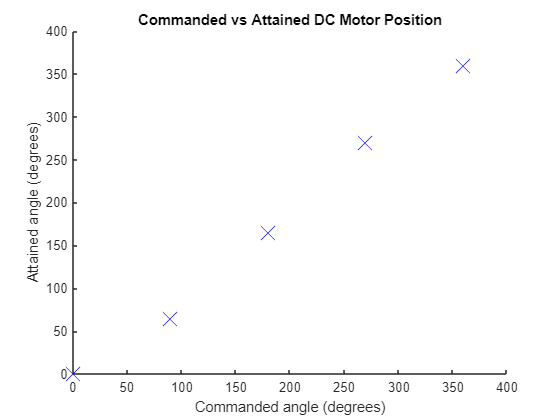

figure(1); hold on; plot(positionData(:,2), positionData(:,1),'bx', MarkerSize=15);
plot(0,0,180,180);
title('Commanded vs Attained DC Motor Position'); xlabel("Commanded angle (degrees)"); ylabel("Attained angle (degrees)");
hold off;

**Robot Functions** (store this code's local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions.

function [robotArduino, positionServo, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot
% controller. Inputs: COM port for the arduino. Returns: Ardunio system
% object called robotArdunio, position servo system object LED system object.
% Pair Programmed by Ivonne and CJ 2022.

% Create global arduino object
% a = arduino('setToYourComputer','Uno','Libraries');
    robotArduino = arduino(COMPORT,'Uno','Libraries','Servo');
    beep; beep; input("Warning! RoboClaw must be OFF before running this code. press RETURN to continue.")
% configure pin 13 as digital-out LED
    blinkLED = 'D13';
    configurePin(robotArduino,blinkLED,'DigitalOutput');

% Create a servo object driving PWM on pin 9
% MinPulseDuration: 1120 (microseconds), center 1520 (microseconds)
% MaxPulseDuration: 1920 (microseconds)

positionServo = servo(robotArduino, 'D9', "MinPulseDuration", 100E-6, 'MaxPulseDuration', 1925E-6)

% RoboClaw in R-C Mode epects to start up with joystick centered. In MATLAB
% functions, servo position is 0-1, so 0.5 (1520μs) is centered.
    writePosition(positionServo, 0.5); % alwasy start servo-command at 0.5
    pause(5.0);                        % wait fro Arduino to send stable PWM
    beep; input("please power up RoboClaw Now, then press RETURN when ready.");
end

function []=Blink(a,LED,n)
for bIndex = 1:n
    writeDigitalPin(a,LED,0);
    pause(0.2)
    writeDigitalPin(a,LED,1);
    pause(0.2)
end
end

**Sense Functions **(Store all sense-related local functions here)

function commandAngle = SENSE()
    commandAngle = input('Enter desired servo angle in degrees:  ');
end

**Think Functions **(Store all think-related local functions here)

function THINK()
    % No thoughts. Only actions
end

**Act Functions **(Store all act-related local functions here)

function [] = ACTRoboClawServoArduino(positionServo, commandAngle)
% This is an example of  afunction to control a RoboCLaw DC motor
% controller in closed-loop, encoder-feeedback-driven position servo
% mode. Need to run SEUPARDUINO function firest to create arduino and
% position servo objects.
% hook Arduino PM pin 9 into Roboclaw digital input 51, hook Arduino ground
% to RoboClawSI Ground.

% Input: Desired position (degrees)
% Output: moves servo motor shaft.
% Ivonne and CJ March 2022

scaleComAngle = (commandAngle/360/2) +0.5
writePosition(positionServo,scaleComAngle);

end